Ejercicio clase

Definiendo la matriz X

X = [-1,-1,-1,-1;
    0.1, 0.3, 0.6, 0.5;
    0.4, 0.7, 0.9, 0.7;
    0.7, 0.2, 0.8, 0.1]

X =    -1.0000   -1.0000   -1.0000   -1.0000
    0.1000    0.3000    0.6000    0.5000
    0.4000    0.7000    0.9000    0.7000
    0.7000    0.2000    0.8000    0.1000


Definiendo el vector d 

d = [1;
    -1; 
    -1;
    1]

d =      1
    -1
    -1
     1


Definiendo el vector W 

W = [0.2;
    0.3;
    0.7;
    0.9];

Taza de aprendizaje 

Eta = 0.8

Eta = 0.8000

Estableciendo el contador 

Epoca = 0

Epoca = 0

Estableciendo el error: 

Error = 1

Error = 1

Funcion

function [salida1] = funciong(entrada1)
    if entrada1>0
        salida1=1;
    elseif entrada1<0
        salida1=-1;
    else 
        salida1=0;
    end
end 

Entrenamiento

while Epoca<2
    for i=1:4
        u = W' * X(:,i) ;
        y = funciong(u); 
        if y ~= d(i) 
            W = W + Eta*(d(i)-y)*X(:,i); 
            Error = 1;
        else 
            Error =0; 
        end
    end 
    Epoca = Epoca + 1;

end 
disp(Epoca);

     2



disp("El vector resultante es:");

El vector resultante es:


disp(W);

    0.2000
    0.9400
    0.7000
    0.5800



calculo de Plano 

theta = W(1); 
w1 = W(2); 
w2 = W(3); 
w3 = W(4);

Extrapolando este ejemplo para x3 tenemos que

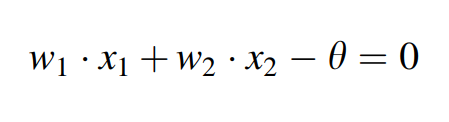

w1*x1 + w2*x2 + w3*x3 - w1 == 0

[x1_plano, x2_plano] = meshgrid(0:0.05:1, 0:0.05:1);
x3_plano = (theta - (w1 * x1_plano) - (w2 * x2_plano)) / w3;

Graficas

disp('Gráfica 3D');

Gráfica 3D


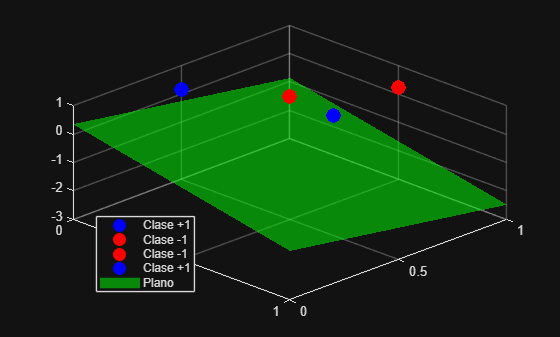

figure('Name', 'Perceptrón');
hold on;
plot3(X(2, 1),X(3, 1),X(4, 1),'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b', 'DisplayName', 'Clase +1');
plot3(X(2, 2),X(3, 2),X(4, 2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'Clase -1');
plot3(X(2, 3),X(3, 3),X(4, 3), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'Clase -1');
plot3(X(2, 4),X(3, 4),X(4, 4),'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b', 'DisplayName', 'Clase +1');
%plano 
surf(x1_plano, x2_plano, x3_plano, 'FaceColor', 'g', 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', 'Plano');
legend('Location', 'best');
grid on
view(45, 45)